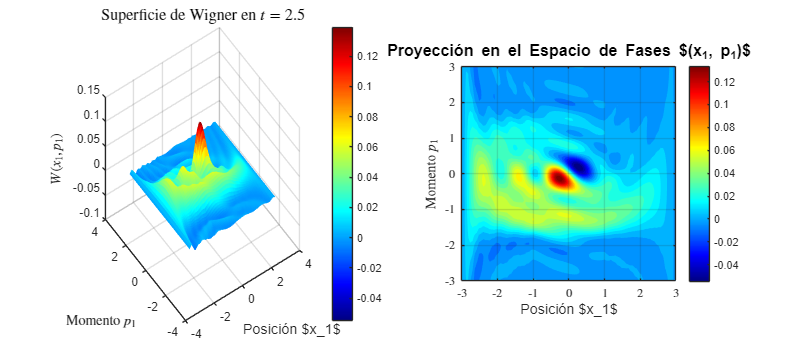

%% MODELO TOE - FUNCIÓN DE WIGNER EN EL ESPACIO DE FASES W(x,p)
% Reconstrucción del estado vibracional de la Fuente 1

clear; clc; close all;

%% 1. PARÁMETROS DEL SISTEMA
hbar = 1; g = 1.0; lambda = 0.8; % Régimen de acoplamiento fuerte
w1 = 1.0; w2 = 1.0; w3 = 1.0;
n_max = 5; % Elevamos un poco n_max para mejor resolución espacial (0..5)

dim_q = 3; dim_osc = n_max + 1;
dim_single = dim_q * dim_osc;
dim_total = dim_single^3;

%% 2. OPERADORES BASE
X_q = [0 0 1; 1 0 0; 0 1 0];
a_osc = zeros(dim_osc);
for n = 1:(dim_osc-1), a_osc(n, n+1) = sqrt(n); end
adag_osc = a_osc'; N_osc = adag_osc * a_osc;

I_q = eye(dim_q); I_osc = eye(dim_osc); I_single = eye(dim_single);

%% 3. EXTENSIÓN AL ESPACIO TOTAL
X1 = kron(kron(X_q, I_osc), kron(I_single, I_single));
a1 = kron(kron(I_q, a_osc), kron(I_single, I_single)); adag1 = a1';
N1 = kron(kron(I_q, N_osc), kron(I_single, I_single));

X2 = kron(kron(I_single, kron(X_q, I_osc)), I_single);
a2 = kron(kron(I_single, kron(I_q, a_osc)), I_single); adag2 = a2';
N2 = kron(kron(I_single, kron(I_q, N_osc)), I_single);

X3 = kron(I_single, kron(I_single, kron(X_q, I_osc)));
a3 = kron(I_single, kron(I_single, kron(I_q, a_osc))); adag3 = a3';
N3 = kron(I_single, kron(I_single, kron(I_q, N_osc)));

H0 = hbar*w1*(N1 + 0.5*eye(dim_total)) + ...
     hbar*w2*(N2 + 0.5*eye(dim_total)) + ...
     hbar*w3*(N3 + 0.5*eye(dim_total));
H_dir = (hbar * g / 2) * (X1*X2*X3 + X1'*X2'*X3');
H_osc_dir = hbar * lambda * (X1*adag1 + X1'*a1 + X2*adag2 + X2'*a2 + X3*adag3 + X3'*a3);

H_total = H0 + H_dir + H_osc_dir;

%% 4. ESTADO INICIAL |Psi_0>
v_x = [1;0;0]; v_y = [0;1;0]; v_z = [0;0;1];
v_0 = zeros(dim_osc, 1); v_0(1) = 1;

ket_xyz0 = kron(kron(kron(v_x,v_0), kron(v_y,v_0)), kron(v_z,v_0));
ket_yzx0 = kron(kron(kron(v_y,v_0), kron(v_z,v_0)), kron(v_x,v_0));
ket_zxy0 = kron(kron(kron(v_z,v_0), kron(v_x,v_0)), kron(v_y,v_0));

psi_0 = (1/sqrt(3)) * (ket_xyz0 + ket_yzx0 + ket_zxy0);

%% 5. EVOLUCIÓN TEMPORAL
t_target = 2.5; % Instante próximo al mínimo de fidelidad
[V, D] = eig(H_total);
psi_t = V * ((V' * psi_0) .* exp(-1i * diag(D) * t_target / hbar));

%% 6. TRAZA PARCIAL PARA OBTENER rho_osc1 (Matriz densidad del Oscilador 1)
% Reagrupamos índices para trazar (Dirección 1,2,3 y Osciladores 2,3)
% Dejando solo el subespacio del Oscilador 1 (dim_osc x dim_osc)
Psi_tensor = reshape(psi_t, [dim_q, dim_osc, dim_q, dim_osc, dim_q, dim_osc]);
% Permutamos para dejar Oscilador 1 al principio
Psi_perm = permute(Psi_tensor, [2, 1, 3, 4, 5, 6]);
Psi_mat = reshape(Psi_perm, [dim_osc, dim_q^3 * dim_osc^2]);

rho_osc1 = Psi_mat * (Psi_mat'); % Matriz densidad reducida 6x6 del oscilador 1

%% 7. CÁLCULO DE LA FUNCIÓN DE WIGNER W(x, p)
x = linspace(-3, 3, 100);
p = linspace(-3, 3, 100);
[X, P] = meshgrid(x, p);
W = zeros(size(X));

% Base de funciones de onda del oscilador armónico psi_n(x)
psi_n = zeros(dim_osc, length(x));
for n = 0:(dim_osc-1)
    % Polinomio de Hermite
    H_n = hermitePoly(n, x);
    psi_n(n+1, :) = (1/pi^(1/4)) * (1/sqrt(2^n * factorial(n))) .* H_n .* exp(-x.^2 / 2);
end
% Cálculo de Wigner vía integral de solapamiento en x
for ix = 1:length(x)
    for ip = 1:length(p)
        x_val = X(ip, ix);
        p_val = P(ip, ix);
        
        % Integración sobre la coordenada y: <x-y/2| rho |x+y/2> * exp(2i p y)
        y = linspace(-4, 4, 101);
        dy = y(2) - y(1);
        integrand = 0;
        
        for n = 0:(dim_osc-1)
            for m = 0:(dim_osc-1)
                if abs(rho_osc1(n+1, m+1)) > 1e-6
                    psi_m_plus = interp1(x, psi_n(m+1,:), x_val + y/2, 'linear', 0);
                    psi_n_minus = interp1(x, psi_n(n+1,:), x_val - y/2, 'linear', 0);
                    
                    term = rho_osc1(n+1, m+1) * psi_m_plus .* psi_n_minus .* exp(2i * p_val * y);
                    integrand = integrand + sum(term) * dy;
                end
            end
        end
        W(ip, ix) = real(integrand) / (2*pi);
    end
end

%% 8. REPRESENTACIÓN GRÁFICA (SURF 3D Y CONTURNO 2D)
figure('Color', [1 1 1], 'Position', [100 100 900 400]);

% Panel 1: Superficie 3D
subplot(1,2,1);
surf(X, P, W, 'EdgeColor', 'none');
colormap(jet); colorbar; view([-35 45]);
xlabel('Posición $x_1$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Momento $p_1$', 'Interpreter', 'latex', 'FontSize', 12);
zlabel('$W(x_1, p_1)$', 'Interpreter', 'latex', 'FontSize', 12);
title(sprintf('Superficie de Wigner en $t = %.1f$', t_target), 'Interpreter', 'latex', 'FontSize', 13);

% Panel 2: Mapa de Contornos 2D
subplot(1,2,2);
contourf(X, P, W, 30, 'LineColor', 'none');
colormap(jet); colorbar; axis square;
xlabel('Posición $x_1$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Momento $p_1$', 'Interpreter', 'latex', 'FontSize', 12);
title('Proyección en el Espacio de Fases $(x_1, p_1)$', 'FontSize', 13);
grid on; set(gca, 'TickLabelInterpreter', 'latex');


%% FUNCIÓN AUXILIAR PARA POLINOMIOS DE HERMITE
function H = hermitePoly(n, x)
    if n == 0
        H = ones(size(x));
    elseif n == 1
        H = 2 * x;
    elseif n == 2
        H = 4 * x.^2 - 2;
    elseif n == 3
        H = 8 * x.^3 - 12 * x;
    elseif n == 4
        H = 16 * x.^4 - 48 * x.^2 + 12;
    elseif n == 5
        H = 32 * x.^5 - 160 * x.^3 + 120 * x;
    end
end